% Create optimization variables
p = optimvar("p",3,1,"LowerBound",20,"UpperBound",200);

% Set initial starting point for the solver
initialPoint.p = zeros(size(p));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@filter1,p);

% Set nondefault solver options
options = optimoptions("fmincon","PlotFcn",["optimplot","optimplotx",...
    "optimplotfval"]);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       p

	minimize :
       filter1(p)


	variable bounds:
       20 <= p(1) <= 200
       20 <= p(2) <= 200
       20 <= p(3) <= 200




Solving problem using fmincon.


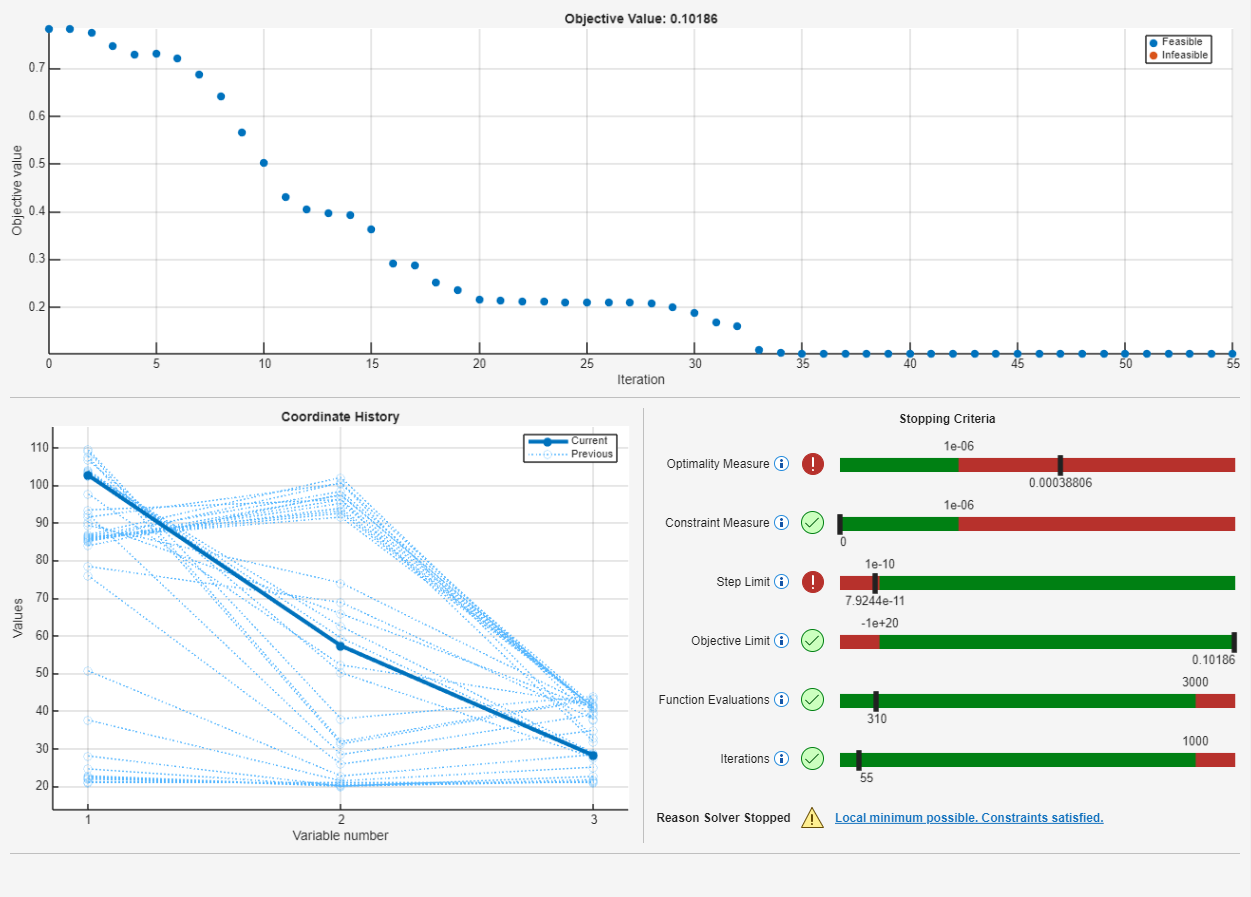

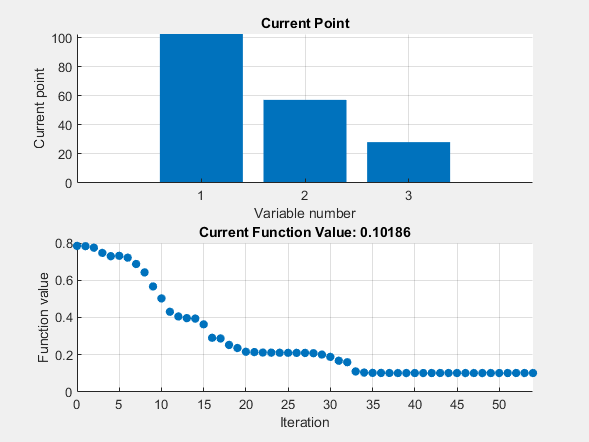


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","fmincon","Options",options);


% Display results
solution

solution = struct with fields:
    p: [3×1 double]


reasonSolverStopped

reasonSolverStopped =     StepSizeBelowTolerance


objectiveValue

objectiveValue = 0.1019


% Clear variables
clearvars p initialPoint options reasonSolverStopped objectiveValue